## Transfer Learning Using AlexNet

In this lab, you will explore transfer learning using Alexnet. AlexNet has been trained on over a million images and can classify images into 1000 object categories (such as keyboard, coffee mug, pencil, and many animals). The network has learned rich feature representations for a wide range of images. The network takes an image as input and outputs a label for the object in the image together with the probabilities for each of the object categories. AlexNet won ImageNet competition in 2012, achieving highest classification performance.

## 1)     Load Image Data

The dataset contains 750 color images in 3 categories {‘`caprese_salad`’, ‘`french_fries`’, ‘pizza’}. You will use `an imageDataStore object to read images. First, ` create an ImageDatastore object using the imageDatastore function, specify its properties and then import and process the data using object functions. `An ``imageDatastore ` automatically labels the images based on folder names and stores the data as an `ImageDatastore`object.  

clear all;

%add code here
%using the imageDatastore, load the images and labels. See the documents for the details.

imagepath = 'foodImages';
imds = imageDatastore(imagepath, 'IncludeSubfolders',true, 'LabelSource','foldernames');


%add code
%Task1: By referencing the Matlab documentation about the imageDatastore() function,
% display the number of labels in the provided data and count of each category

% display # of labels and count of each

imds.countEachLabel

ans = 3×2 table
        Label        Count
    _____________    _____

    caprese_salad    250  
    french_fries     250  
    pizza            250  


## 2)     Splitting the data

Before we start training, divide the data into training, validation, and test data sets. You will use 60% of images per category to train, 20% for validation, and specify 20% as a test set to test the food classification model after it has been trained. Use the **splitEachLabel**() function to  split the  ImageDatastore labels  by propositions. See the document for the details about the **splitEachLabel**() function.

%add code
% Using the splitEachLabel() function, split the data for training, testing and validation sets.

[trainDS, testDS, valDS] = splitEachLabel(imds, 0.6,0.2,0.2,'randomized');




%add code
% Task2: Display the count for each category in training,
% testing, validation data sets.
% display # of labels and count of each

trainDS.countEachLabel

ans = 3×2 table
        Label        Count
    _____________    _____

    caprese_salad    150  
    french_fries     150  
    pizza            150  


testDS.countEachLabel

ans = 3×2 table
        Label        Count
    _____________    _____

    caprese_salad    50   
    french_fries     50   
    pizza            50   


valDS.countEachLabel

ans = 3×2 table
        Label        Count
    _____________    _____

    caprese_salad    50   
    french_fries     50   
    pizza            50   


**3) Visualize**  **the Data**

As a first step, the first 16 training examples are visualized. They correspond to images of three different categories. 

- Display the randomly selected 16 image samples from the training dataset.  Generate 16 numbers in the range of [1, number of the training samples] using the **randperm**() function. Then, extract the image samples from the training data using the indexes generated by the **randperm**() function. 

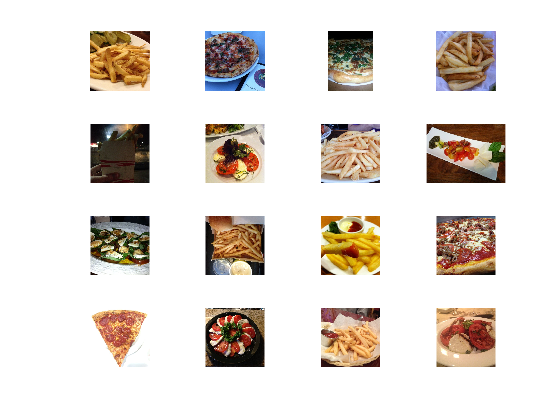

% Add code
% We can visually inspect individual images
% extract one samples frome each category

numTrainImages = numel(trainDS.Labels);
idx = randperm(numTrainImages, 16);

figure
for i = 1:16
    subplot(4,4,i)
    foodImg = readimage(trainDS, idx(i));
    imshow(foodImg)
    
end

**4) Load the pretrained Alex Network**

Load the pretrained AlexNet neural network. If Neural Network Toolbox™ Model *for AlexNet Network* is not installed, then the software provides a download link. AlexNet is trained on more than one million images and can classify images into 1000 object categories, such as keyboard, mouse, pencil, and many animals. As a result, the model has learned rich feature representations for a wide range of images. To load the pretrained Alexnet,

%add code
%load the pretrained alex net


net = alexnet;


%add code
% Display the network architecture.
net.Layers

ans =   25x1 Layer array with layers:

     1   'data'     Image Input                   227x227x3 images with 'zerocenter' normalization
     2   'conv1'    Convolution                   96 11x11x3 convolutions with stride [4  4] and padding [0  0  0  0]
     3   'relu1'    ReLU                          ReLU
     4   'norm1'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     5   'pool1'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
     6   'conv2'    Convolution                   256 5x5x48 convolutions with stride [1  1] and padding [2  2  2  2]
     7   'relu2'    ReLU                          ReLU
     8   'norm2'    Cross Channel Normalization   cross channel normalization with 5 channels per element
     9   'pool2'    Max Pooling                   3x3 max pooling with stride [2  2] and padding [0  0  0  0]
    10 




%add code to get the pretrained image size
inputSize = net.Layers(1).InputSize;








The network requires input images of size 227-by-227-by-3, but input images may have sizes that are different from the pre-trained network, so we want to preprocess images, resize them to be consistent with pre-trained networks.

%add code
% Resize all of the data.
% The resize function can be specified as ReadFcn object fucntion in imageDatastore object.
AlexNetImageSize =net.Layers(1).InputSize(1:2);                                                 %different from given code but should still work
trainDS.ReadFcn = @(loc)imresize(imread(loc), AlexNetImageSize);
testDS.ReadFcn = @(loc)imresize(imread(loc), AlexNetImageSize);
valDS.ReadFcn = @(loc)imresize(imread(loc), AlexNetImageSize);





**5) Re****place Final Layers**

 The last three layers of the pretrained network `net` are configured for 1000 classes. These three layers must be fine-tuned for the new classification problem. Extract all layers, except the last three, from the pretrained network.

The pre-trained layers at the end of the network are designed to classify 1000 objects. But we need to classify different objects now. So the first step in transfer learning is to replace alter just three of the layers of the pre-trained network with a set of layers that can classify 3 classes. 

 Specify the options of the new fully connected layer according to the new data. Set the fully connected layer to have the same size as the number of classes in the new data.

%add code
%Replace the final layers

layersTransfer = net.Layers(1:end-3);


**6) Train Network**

 First, specify the training options using the [`trainingOptions`](https://www.mathworks.com/help/nnet/ref/trainingoptions.html)`()` function. For transfer learning, keep the features from the early layers of the pretrained network (the transferred layer weights). To slow down learning in the transferred layers, set the initial learning rate to a small value. When performing transfer learning, you do not need to train for as many epochs. An epoch is a full training cycle on the entire training data set. Specify the mini-batch size and validation data. The software validates the network every `ValidationFrequency` iterations during training. See the Matlab document for the details. 

%add code for the network training options

numClasses = numel(categories(trainDS.Labels));


% If you get an out of memory error, consider changing the 'MiniBatchSize' to a lower value.
% Training with the optimized set of hyperparameters
%add code for the training


layers = [
    layersTransfer %pretrained alexNet except for lat three layers
    fullyConnectedLayer(numClasses)
    softmaxLayer
    classificationLayer
    ];


**7) Classify Test Images**

**Task4**: Classify the test images using the trained network. Use the test data to measure the classification accuracy of the network.  

Training on single GPU.
Initializing image normalization.
|=======================================================================================================================|
|     Epoch    |   Iteration  | Time Elapsed |  Mini-batch  |  Validation  |  Mini-batch  |  Validation  | Base Learning|
|              |              |  (seconds)   |     Loss     |     Loss     |   Accuracy   |   Accuracy   |     Rate     |
|=======================================================================================================================|
|            1 |            1 |         3.16 |       1.6547 |       1.0104 |       29.69% |       51.33% |       0.0010 |
|            1 |            5 |        15.47 |       0.6112 |       0.3147 |       70.31% |       91.33% |       0.0010 |
|            2 |           10 |        28.57 |       0.2163 |       0.1914 |       93.75% |       94.67% |       0.0010 |
|            3 |           15 |        42.65 |       0.1587 |       0.1698 |       90.63

netTransfer =   SeriesNetwork with properties:

    Layers: [25×1 nnet.cnn.layer.Layer]


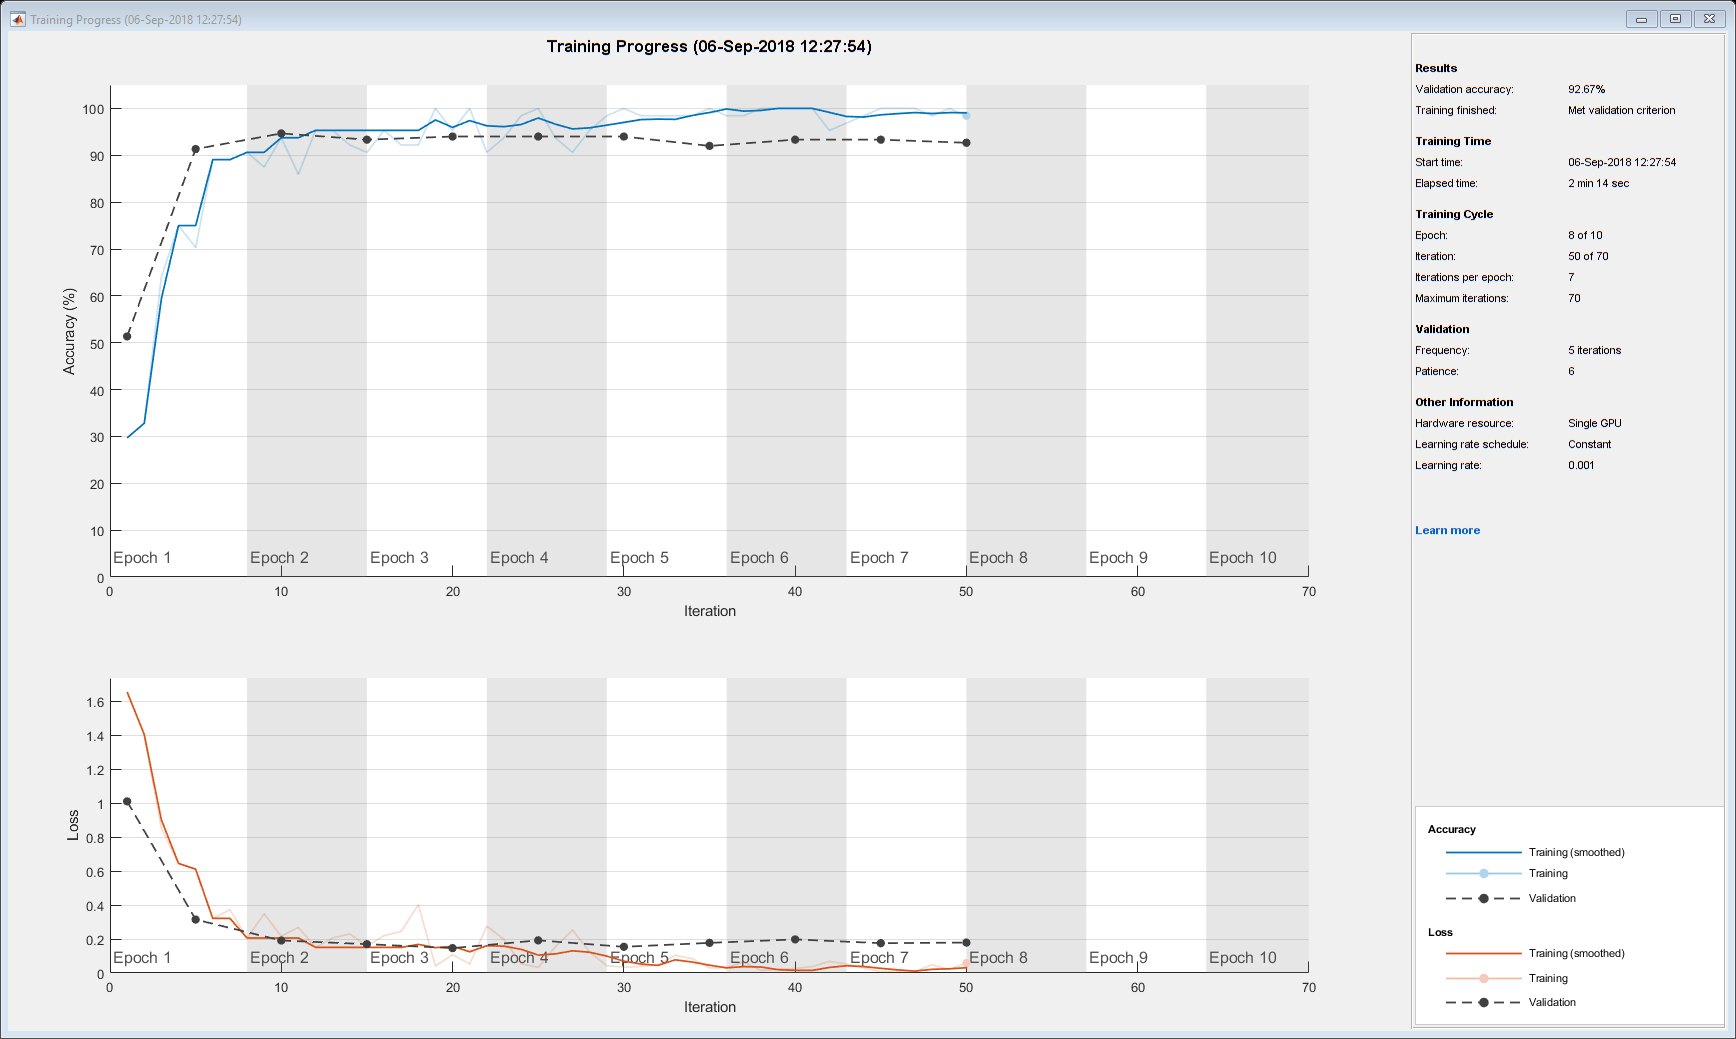

%add code
%calculate the performance of the trained net.
opts = trainingOptions('sgdm',...
    "InitialLearnRate",0.001,...
    'ValidationData',valDS,...
    'Plots', 'training-progress',...
    'ValidationFrequency',5,...
    'MaxEpochs',10,...
    'MiniBatchSize',64,...
    'ValidationPatience',6);

netTransfer = trainNetwork(trainDS,layers,opts)

[pred, score] = classify(netTransfer, testDS);
% accuracy = sum(pred == testDS.Labels);
% accuracy = accuracy/numel(testDS.Labels);
acc = fprintf('\nTesting accuracy: %f', sum(pred == categorical(testDS.Labels, 'Ordinal',false))/numel(testDS.Labels)*100);


Testing accuracy: 93.333333

Display four sample test images with their predicted labels as below:

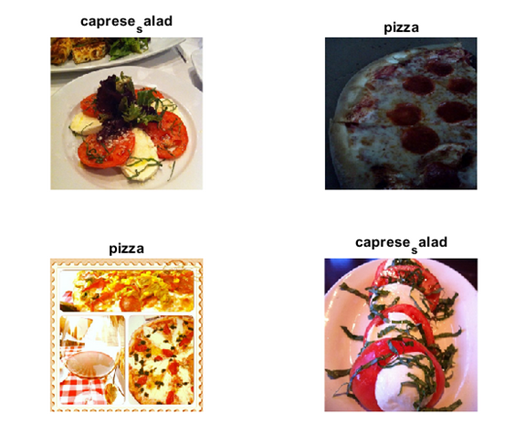

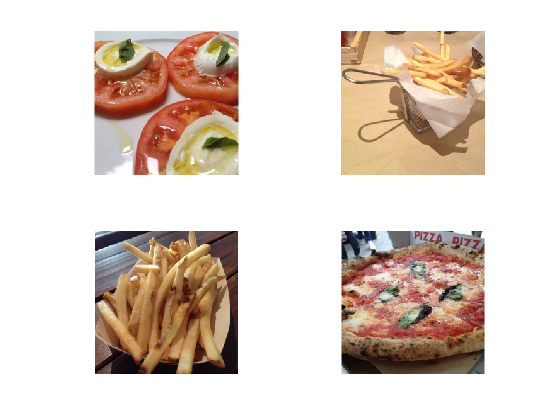

Predicted_class = categorical
     caprese_salad 


Predicted_class = categorical
     french_fries 


Predicted_class = categorical
     french_fries 


Predicted_class = categorical
     pizza 



%add code
% Display four sample test images with their predicted labels as below:
numTrainImages = numel(testDS.Labels);
idx = randperm(numTrainImages, 4);

figure
for i = 1:4
    subplot(2,2,i)
    foodImg = readimage(testDS, idx(i));
    imshow(foodImg)
    Predicted_class = classify(netTransfer, foodImg)
end